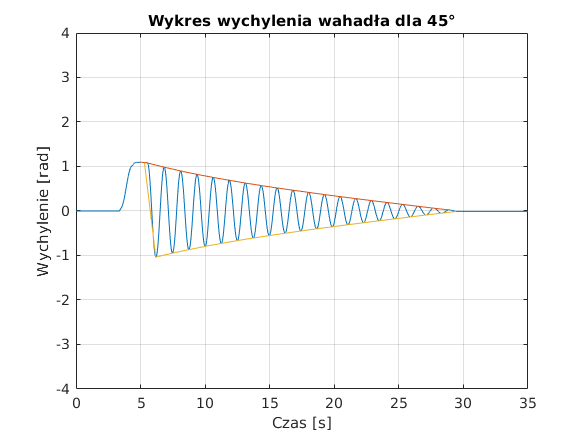

close all;
clear all;
load("dane_pomiarowe/15_10_2020/45stopni_wahadlo.mat");

start = 162;
time = P1_ExpData.time(start:end)-start*0.01;
arc = P1_ExpData.signals(4).values(start:end);
plot(time, arc)
grid on;
hold on;
title('Wykres wychylenia wahadła dla 45°')
xlabel('Czas [s]')
ylabel('Wychylenie [rad]')
axis([0 35 -4 4])
[peaks, locs] = findpeaks(arc);
plot(time(locs), peaks)
[bot_peaks, bot_locs] = findpeaks(-arc);
plot(time(bot_locs), -bot_peaks)

hold off;
bot_l = bot_locs(3:end);
bot_p = bot_peaks(3:end);
max(arc);
T_45 = mean(diff(time(locs)))

T_45 = 1.1920

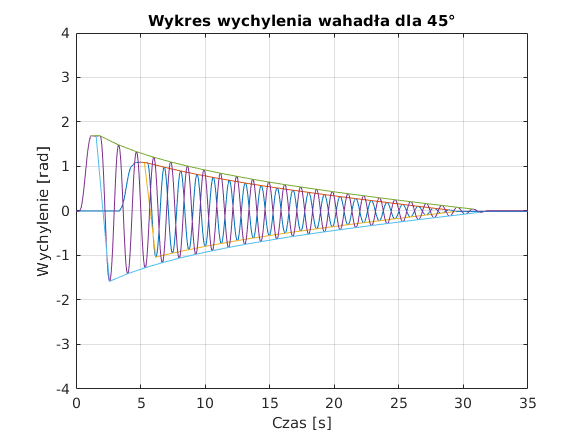

load("dane_pomiarowe/15_10_2020/90stopni_wahadlo.mat");

start = 162;
time = P1_ExpData.time(start:end)-start*0.01;
arc = P1_ExpData.signals(4).values(start:end);
plot(time, arc)
grid on;
hold on;
title('Wykres wychylenia wahadła dla 45°')
xlabel('Czas [s]')
ylabel('Wychylenie [rad]')
axis([0 35 -4 4])
[peaks, locs] = findpeaks(arc);
plot(time(locs), peaks)
[bot_peaks, bot_locs] = findpeaks(-arc);
plot(time(bot_locs), -bot_peaks)

bot_l = bot_locs(3:end);
bot_p = bot_peaks(3:end);
max(arc);
T_90 = mean(diff(time(locs)))

T_90 = 1.2304

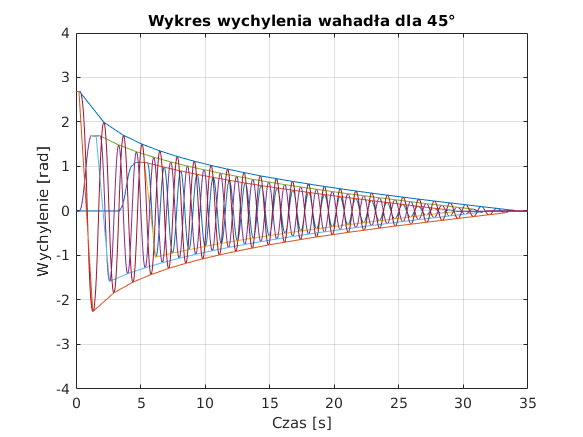

load("dane_pomiarowe/15_10_2020/135stopni_wahadlo.mat");

start = 162;
time = P1_ExpData.time(start:end)-start*0.01;
arc = P1_ExpData.signals(4).values(start:end);
plot(time, arc)
grid on;
hold on;
title('Wykres wychylenia wahadła dla 45°')
xlabel('Czas [s]')
ylabel('Wychylenie [rad]')
axis([0 35 -4 4])
[peaks, locs] = findpeaks(arc);
plot(time(locs), peaks)
[bot_peaks, bot_locs] = findpeaks(-arc);
plot(time(bot_locs), -bot_peaks)

bot_l = bot_locs(3:end);
bot_p = bot_peaks(3:end);
max(arc);
T_135 = mean(diff(time(locs)))

T_135 = 1.2444

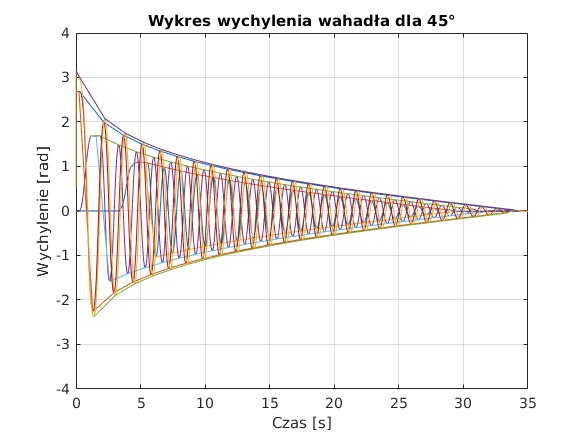

load("dane_pomiarowe/15_10_2020/180.mat");

start = 162;
time = P1_ExpData.time(start:end)-start*0.01;
arc = P1_ExpData.signals(4).values(start:end);
plot(time, arc)
grid on;
hold on;
title('Wykres wychylenia wahadła dla 45°')
xlabel('Czas [s]')
ylabel('Wychylenie [rad]')
axis([0 35 -4 4])
[peaks, locs] = findpeaks(arc);
plot(time(locs), peaks)
[bot_peaks, bot_locs] = findpeaks(-arc);
plot(time(bot_locs), -bot_peaks)

bot_l = bot_locs(3:end);
bot_p = bot_peaks(3:end);
max(arc);
T_180 = mean(diff(time(locs)))

T_180 = 1.3042

T = (T_45 + T_90 + T_135 + T_180)/4

T = 1.2428

J_cumulative = (T.^2 *(0.033*2) * 9.81 * 0.25)/(4*pi.^2)

J_cumulative = 0.0063